# Etude d'un système MIMO : Hélicoptère RC

`à exectuer section par section.`

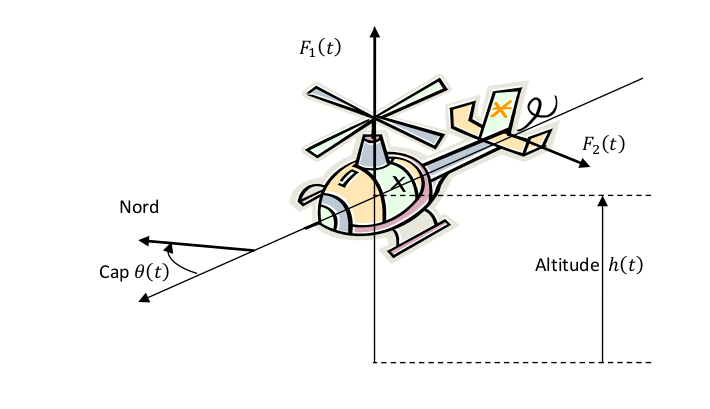

## Sujets abordés

- commandabilité

- retour d'état avec intégrateur

- commande de système MIMO

- découplage

## Objectif

**On cherche à piloter l'altitude **$h\left(t\right)$ d'un helicoptère modèle réduit à pas fixe. Ce modèle d'hélicoptère se pilote en faisant varier la vitesse de rotation des deux rotors : $\omega_1 \left(t\right)$ la vitesse du rotor principal et $\omega_2 \left(t\right)$ le rotor de queue. Les entrées de commandes sont les couples moteurs appliqués sur les deux rotors $C_1 \left(t\right)$ et $C_2 \left(t\right)\ldotp$ On modélise également le comportement en lacet et le cap $\theta \left(t\right)$ de l'hélicoptère.

En considérant certains effets aerodynamiques et gyroscopiques négligeables, on peut écrire le modèle linéarisé suivant :

M = 5;
Fg = 0.981e1 * M;
alpha(1) = 2;
alpha(2) = 2;
J(1) = 0.2e-1;
J(2) = 0.1e-1;
f(1) = 1;
f(2) = 2;
J_l = 0.1e0;

A = [0 1 0 0 0                  0; 
     0 0 0 0 alpha(1) / M       0; 
     0 0 0 1 0                  0; 
     0 0 0 0 0                  alpha(1) /J_l; 
     0 0 0 0 -f(1) / J(1)       0; 
     0 0 0 0 0                  -f(2) / J(2);];
B = [0 0 0; 0 0 -1 / M; 0 0 0; -0.1e1 / J_l 0 0; 0.1e1 / J(1) 0 0; 0 0.1e1 / J(2) 0;];
C=eye(6);
D = 0;

sys=ss(A,B,C,D);
sys.StateName = {'h','dh','\theta','d\theta','w_1','w_2'};
sys.InputName = {'C_1','C_2','Fg'};
sys.OutputName = sys.StateName;
sys


sys =
 
  A = 
                  h       dh   \theta  d\theta      w_1      w_2
   h              0        1        0        0        0        0
   dh             0        0        0        0      0.4        0
   \theta         0        0        0        1        0        0
   d\theta        0        0        0        0        0       20
   w_1            0        0        0        0      -50        0
   w_2            0        0        0        0        0     -200
 
  B = 
             C_1   C_2    Fg
   h           0     0     0
   dh          0     0  -0.2
   \theta      0     0     0
   d\theta   -10     0     0
   w_1        50     0     0
   w_2         0   100     0
 
  C = 
                  h       dh   \theta  d\theta      w_1      w_2
   h              1        0        0        0        0        0
   dh             0        1        0        0        0        0
   \theta         0        0        1        0        0        0
   d\theta        0        0        0        1  

## Commandabilité

On va étudier l'utilité des actionneurs pour piloter ce système.

n_ctrb_C1C2  = rank(ctrb(sys(:,{'C_1','C_2'})))

n_ctrb_C1C2 = 6

n_ctrb_C1  = rank(ctrb(sys(:,{'C_1'})))

n_ctrb_C1 = 3

n_ctrb_C2  = rank(ctrb(sys(:,{'C_2'})))

n_ctrb_C2 = 3

On constate que chaque actionneur ne peut commander que 3 combinaisons d'états et les trois autres sont non commadables. On va approfondir l'étude pour comprendre l'impact des ces actionneurs sur le système.

### Etude du cas C1

Lire attentivement la documentation de cette fonction :

doc ctrbf

La fonction `ctrbf` permet de décomposer le système sous forme triangulaire où la partie supérieur est la partie non commandable et la partie inférieure la partie commandable.** Cela permet d'obtenir les combinaisons de variables que **$C_1$** peut influencer**.


$$\begin{array}{l}
z=T\;x\\
\dot{x} =A\;x+B\;u\Leftrightarrow \dot{z} =\bar{A} \;z+\bar{B} \;u
\end{array}$$



$$z=\left\lbrack \begin{array}{c}
z_{\textrm{nc}} \\
z_c 
\end{array}\right\rbrack$$
 
$$\bar{A} =\left\lbrack \begin{array}{cc}
A_{\textrm{nc}}  & 0\\
A_{21}  & A_c 
\end{array}\right\rbrack$$
 
$$\bar{B} =\left\lbrack \begin{array}{c}
0\\
B_c 
\end{array}\right\rbrack$$


**Interprétation : **on a un sous-système commandable $\dot{\;z_c } =A_c z+B_c u$ perturbé par le terme $A_{21} \;z_{\textrm{nc}}$ où $z_{\textrm{nc}}$ est indépendant de la commande.

[A,B,C,D] = ssdata(sys(:,{'C_1'}))

A =          0    1.0000         0         0         0         0
         0         0         0         0    0.4000         0
         0         0         0    1.0000         0         0
         0         0         0         0         0   20.0000
         0         0         0         0  -50.0000         0
         0         0         0         0         0 -200.0000


B =      0
     0
     0
   -10
    50
     0


C =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


D =      0
     0
     0
     0
     0
     0


[ABAR,BBAR,CBAR,T,K] = ctrbf(A,B,C)

ABAR =    -7.7637  -38.6902   -1.4326   -0.0000    0.0000   -0.0000
  -38.6132 -191.4024  -12.1382   -0.0000   -0.0000   -0.0000
   -2.5681  -12.7246   -0.8340   -0.0000   -0.0000   -0.0000
    0.0780    0.3904    0.0260   -0.0208    1.0193    0.0000
   -3.8668  -19.1637   -1.2735    0.0387   -1.9023    9.6254
   -0.7711   -3.8627    0.1517   -0.1956    9.6054  -48.0769


BBAR =     0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   50.9902


CBAR =    -0.9792    0.1950    0.0399    0.0400    0.0000         0
   -0.0272    0.0677   -0.9965   -0.0008    0.0407         0
   -0.0392    0.0078    0.0016   -0.9990   -0.0204         0
   -0.0003    0.0026   -0.0399    0.0199   -0.9796   -0.1961
   -0.0001    0.0005   -0.0080    0.0040   -0.1959    0.9806
    0.1973    0.9784    0.0610    0.0000         0         0


T =    -0.9792   -0.0272   -0.0392   -0.0003   -0.0001    0.1973
    0.1950    0.0677    0.0078    0.0026    0.0005    0.9784
    0.0399   -0.9965    0.0016   -0.0399   -0.0080    0.0610
    0.0400   -0.0008   -0.9990    0.0199    0.0040    0.0000
    0.0000    0.0407   -0.0204   -0.9796   -0.1959         0
         0         0         0   -0.1961    0.9806         0


K =      1     1     1     0     0     0


La matrice $T$ est la matrice de passage entre l'état d'origine $x$ et l'état $z$.

On regarde les trois dernières lignes de la matrice T (celles qui correspondent aux états commandables) :

T(end-n_ctrb_C1+1:end,:)

ans =     0.0400   -0.0008   -0.9990    0.0199    0.0040    0.0000
    0.0000    0.0407   -0.0204   -0.9796   -0.1959         0
         0         0         0   -0.1961    0.9806         0


La dernière colonne nous indique qu'en aucun cas on pourra avoir agir sur la vitesse de rotation du rotor 2 (rotor de queue). Chaque ligne indique une combinaison que l'on sera capable de stabiliser (attention cette décomposition n'est pas unique !!). Par exemple, la troisième ligne nous indique que l'on pourra stabiliser la variable :


$$z_6 =-0\ldotp 19{\;x}_4 +0\ldotp 98{\;x}_5 =-0\ldotp 19\;d\theta \;+0\ldotp 98\;\omega_1$$


i.e. une variable qui depends principalement la vitesse de rotation du rotor principal et dans une moindre mesure la vitesse en lacet. 

**Remarque :** on sent bien que la chaine $\omega_1 \to \textrm{dh}\to h$ est la partie principalement commandable via $C_1$. On pourrait chercher une autre matrice de passage $T$ pour faire apparaître cela. Les autres états étant peçus comme une perturbation de cette partie commandable. Pour cela il faut faire la décomposition à la main. Bien que cela soit simple dans ce cas, on ne va pas aller trop loin dans cette analyse.

**Cette partie étant commandable, les valeurs propres qui lui sont associés sont modifiable**, on peut stabiliser et changer le comportement de ces variables. 

***Donc tout va bien pour piloter l'altitude ?***

On regarde maintenant les lignes qui correspondent aux états non commandables :

T(1:n_ctrb_C1,:)

ans =    -0.9792   -0.0272   -0.0392   -0.0003   -0.0001    0.1973
    0.1950    0.0677    0.0078    0.0026    0.0005    0.9784
    0.0399   -0.9965    0.0016   -0.0399   -0.0080    0.0610


Vu que ces états sont non commadables, leur évolution ne dépends pas de la commande :

$z_{\textrm{nc}} \left(t\right)=e^{A_{\textrm{nc}} } z\left(0\right)$ avec ${z_{\textrm{nc}} }_i \left(t\right)=T_i x\left(t\right)$$\;i\in \left\lbrace 1,2,3\right\rbrace$.

avec :

Anc = ABAR(1:n_ctrb_C1,1:n_ctrb_C1);
eig(Anc)

ans = 1.0e+02 *

  -2.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 - 0.0000i


Comme les $A_{\textrm{nc}}$** a deux valeurs propres instables**, on a deux combinaisons de $z_i$ qui divergent. Cela veut dire que sur notre système il y aura forcement **deux variables **$x_i$** qui divergeront.**

Donc si même on stabilise l'altitude avec $C_1$, l'hélicoptère se mettra en rotation sur lui même car deux variables parmi $\theta ,$ $d\theta \;$et $\omega_2$ **divergent** !! Pour savoir quelles variables divergent, il faudrait procéder à une décomposition modale (mais on a pas le temps !). Si le lacet engendrait des perturbations sur les équations de l'altitude (il faudrait modéliser les frottements pour le voir), ces signaux de perturbations divergeraient. Comme il faudrait les compenser par la commande, les signaux de commandes divergenraient également et entreraient rapidement en saturation. **L'hélicoptère ne serait plus controlé et tomberait** (dommage !).

**Remarque :** les seuls cas favorables de système non commadable sont quand toutes les variables non commandables convergent ou alors qu'elles soient inutile au système et quelles ne perturbent pas la partie commandable (peu probable ou alors c'est une erreur dans la modélisation).

### Etude du cas C2


[A,B,C,D] = ssdata(sys(:,{'C_2'}))

A =          0    1.0000         0         0         0         0
         0         0         0         0    0.4000         0
         0         0         0    1.0000         0         0
         0         0         0         0         0   20.0000
         0         0         0         0  -50.0000         0
         0         0         0         0         0 -200.0000


B =      0
     0
     0
     0
     0
   100


C =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


D =      0
     0
     0
     0
     0
     0


[ABAR,BBAR,CBAR,T,K] = ctrbf(A,B,C)

ABAR =   -50.0000         0         0         0         0         0
         0         0   -1.0000         0         0         0
   -0.4000         0         0         0         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0   20.0000
         0         0         0         0         0 -200.0000


BBAR =      0
     0
     0
     0
     0
   100


CBAR =      0     1     0     0     0     0
     0     0    -1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     1     0     0     0     0     0
     0     0     0     0     0     1


T =      0     0     0     0     1     0
     1     0     0     0     0     0
     0    -1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     0     1


K =      1     1     1     0     0     0


eig(ABAR(1:3,1:3))

ans =      0
     0
   -50


Mêmes conclusions. Ici on voit clairement que la chaîne 'altitude' divergera.

### Conclusion

Les ingénieurs en aeronautique on bien fait de mettre un rotor de queue !! **Ce type d'analyse est très utile lors de la conception **d'un système. Avant même de mettre en place des actionneurs sur un système, on peut déterminer ceux qui auront le plus d'effet et quelles variables pourront être contrôlée efficacement. On peut transposer cette étude avec l'observabilité et permettre de déterminer pendant la phase de conception d'un système quels capteurs seraient les plus appropriés. Faire ces analyses ainsi que concevoir le système de commande en même temps que le système lui même s'appelle faire de la **conception intégrée** (ou encore mécatronique). C'est une méthode efficace pour obtenir un prototype fonctionnel **rapidement tout en réduisant les coûts **de prototypage et de test.

## Commande MIMO

Réalisons la commande du système. Il nous faut **compenser la gravité (perturbation)**, on va donc insérer des **intégrateurs**. Comme nous avons** deux entrées, on peut asservir deux sorties**, on va choisir $h$ pour répondre au cahier des charges initial et $\theta \;$ pour compenser le problème de variation du cap.

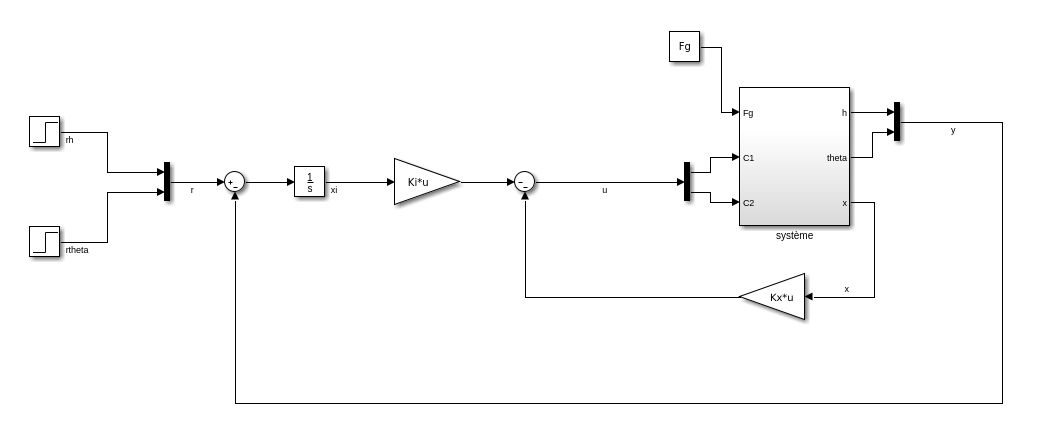

ce qui est équivalent à

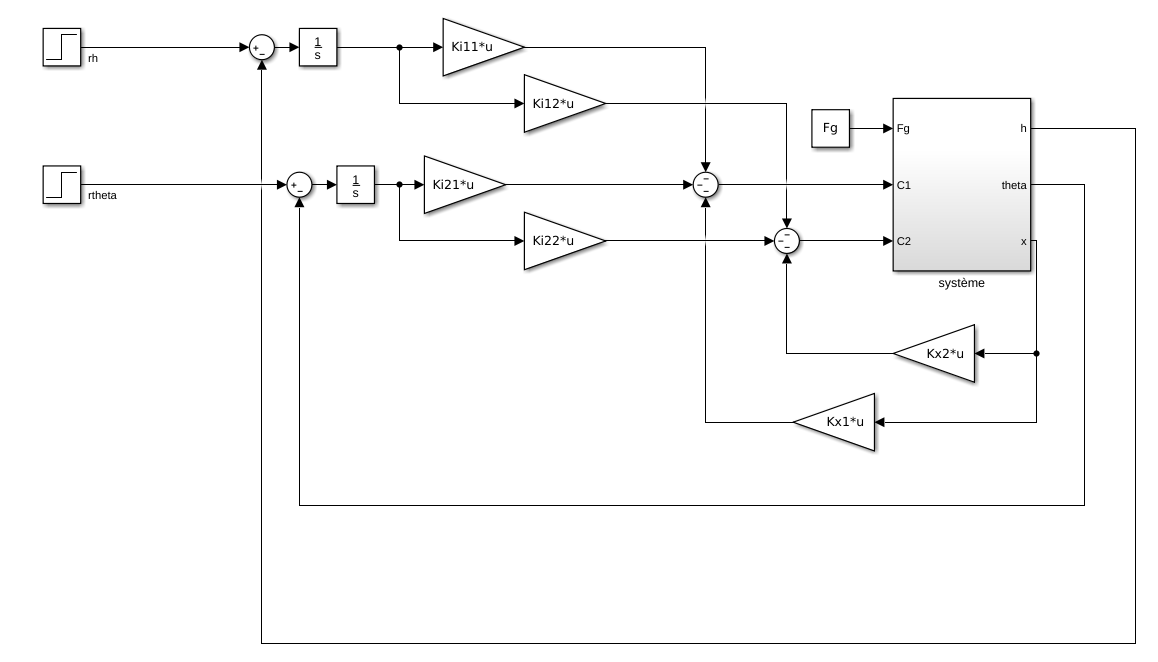

On utilise la **méthode LQ** pour le réglage des gains.

[A,B,C,D] = ssdata(sys); % on récupère les matrices

Cc = sys({'h','\theta'},:).c; % définition des sorties à asservir

% on augmente le système en ajoutant des intégrateurs :
A_aug = [A zeros(6,2);
        -Cc zeros(2,2)];
    
% les entées du système
B_aug = [B;zeros(2,3)]; 

% on décompose les entrée entre celles qui commande le système et les
% autres

B_aug_comm = B_aug(:,1:2);% les entrées utilisées pour la commande du système (C1 et C2)
B_aug_d = B_aug(:,3); % les entrées de perturbations

% les entrées de consigne
B_r = [zeros(6,2);eye(2)];

Caug=eye(8); % pour voir tout l'état lors des simulations avec step.

% Calcul par la méthode LQ
Q=eye(8); % on fixe les matrices de pondération.
R=eye(2);
K=lqr(A_aug,B_aug_comm,Q,R); % calcul des gains.

% calcul du système en boucle fermée qui a pour entrée les consignes et la
% perturbation.
sys_bf = ss(A_aug-B_aug_comm*K,[B_r B_aug_d],Caug,0);
% on nomme les états
for i =1:6
    sys_bf.StateName{i} = sys.StateName{i};
end
sys_bf.StateName{7} = 'xi1';
sys_bf.StateName{8} = 'xi2';
% on nomme les E/S du système
sys_bf.InputName = {'rh','rtheta','Fg'};
sys_bf.OutputName = sys_bf.StateName;
% on affiche le résultat
sys_bf


sys_bf =
 
  A = 
                  h       dh   \theta  d\theta      w_1      w_2      xi1      xi2
   h              0        1        0        0        0        0        0        0
   dh             0        0        0        0      0.4        0        0        0
   \theta         0        0        0        1        0        0        0        0
   d\theta    26.75    43.44   -11.58   -6.885    4.053    19.42   -7.597    6.502
   w_1       -133.7   -217.2    57.89    34.42   -70.27    2.877    37.99   -32.51
   w_2         -233   -383.2     -140   -92.54   -6.999   -231.7    65.02    75.97
   xi1           -1        0        0        0        0        0        0        0
   xi2            0        0       -1        0        0        0        0        0
 
  B = 
                rh  rtheta      Fg
   h             0       0       0
   dh            0       0    -0.2
   \theta        0       0       0
   d\theta       0       0       0
   w_1           0       0       0
   w_2         

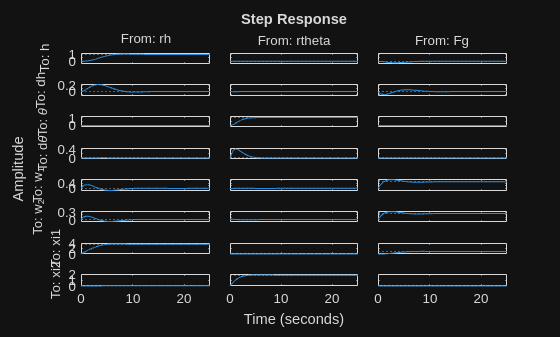

% simulation pour des échelons.
step(sys_bf)

On observe ce qu'il se passe au nievau du lacet si on demande un changement d'altitude de 20m.

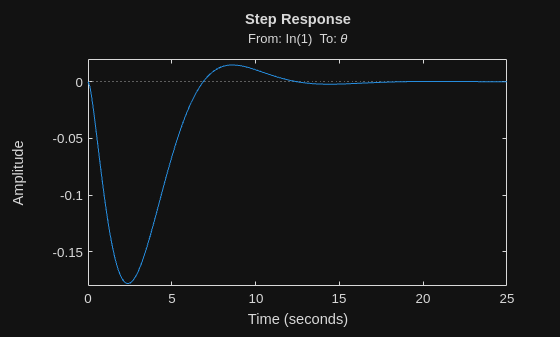

% on se focalise sur le transfert entre la consigne en altitude et le
% lacet.
step(sys_bf('\theta','rh')*20);

**On constate un couplage** entre la consigne $r_h$ et l'angle de lacet. Ce comportement peut être indésirable : cette déviation est proportionelle à l'amplitude de la commande et peut pousser l'hélicoptère à faire plusieurs tours sur lui même pendant la montée avant de revenir à son cap de départ (pas terrible).

### Découplage

Ceci peut être confirmé en étudiant la matrice de transfert entre les consignes et les sorties :

W=tf(sys_bf({'h','\theta'},{'rh','rtheta'}))


W =
 
  From input "rh" to output...
                                  15.19 s^4 + 3595 s^3 + 4.603e04 s^2 + 7.267e04 s + 4e04
   h:  -------------------------------------------------------------------------------------------------------------
       s^8 + 308.8 s^7 + 2.013e04 s^6 + 2.386e05 s^5 + 6.173e05 s^4 + 7.72e05 s^3 + 5.354e05 s^2 + 2.146e05 s + 4e04
 
                                  -7.597 s^5 - 876.9 s^4 - 3815 s^3 - 3478 s^2 - 1235 s + 2.461e-14
   \theta:  -------------------------------------------------------------------------------------------------------------
            s^8 + 308.8 s^7 + 2.013e04 s^6 + 2.386e05 s^5 + 6.173e05 s^4 + 7.72e05 s^3 + 5.354e05 s^2 + 2.146e05 s + 4e04
 
  From input "rtheta" to output...
                                    -13 s^4 - 2925 s^3 - 3146 s^2 - 1235 s - 7.279e-14
   h:  -------------------------------------------------------------------------------------------------------------
       s^8 + 308.8 s^7 + 2.013e04 s^6 + 2.386e05 s^

Rappel : la matrice de transfert d'un système MIMO :


$$\left\lbrack \begin{array}{c}
h\left(s\right)\\
\theta \left(s\right)\;
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
F_{r_h \to h}  & F_{r_{\theta \;} \to h} \\
F_{r_h \to \theta \;}  & F_{r_{\theta \;} \to \theta \;} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
r_h \left(s\right)\\
r_{\theta \;} \left(s\right)
\end{array}\right\rbrack$$


donc on a $\theta \left(s\right)=$$F_{r_h \to \theta }$$r_h \left(s\right)$+$F_{r_{\theta \;} \to \theta }$$r_{\theta \;} \left(s\right)$.

**Le couplage vient des termes hors diagonale** (ici $F_{r_{\theta \;} \to h}$ et $F_{r_h \to \theta \;}$). Si on veut éliminer leurs effets, il faut s'arranger pour les rendre nuls. Pour cela on peut, par exemple, ajouter un** pré-traitement** sur les canaux de consigne qui effecturerait le remplacement :


$$\left\lbrack \begin{array}{c}
r_h \left(s\right)\\
r_{\theta \;} \left(s\right)
\end{array}\right\rbrack \to \left\lbrack \begin{array}{cc}
I & -\frac{F_{r_{\theta \;} \to h} }{F_{r_h \to h} }\\
-\frac{F_{r_{h\;} \to \theta } }{F_{r_{\theta \;} \to \theta } } & I
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
r_h \left(s\right)\\
r_{\theta \;} \left(s\right)
\end{array}\right\rbrack$$


ce qui correspond au schéma suivant :

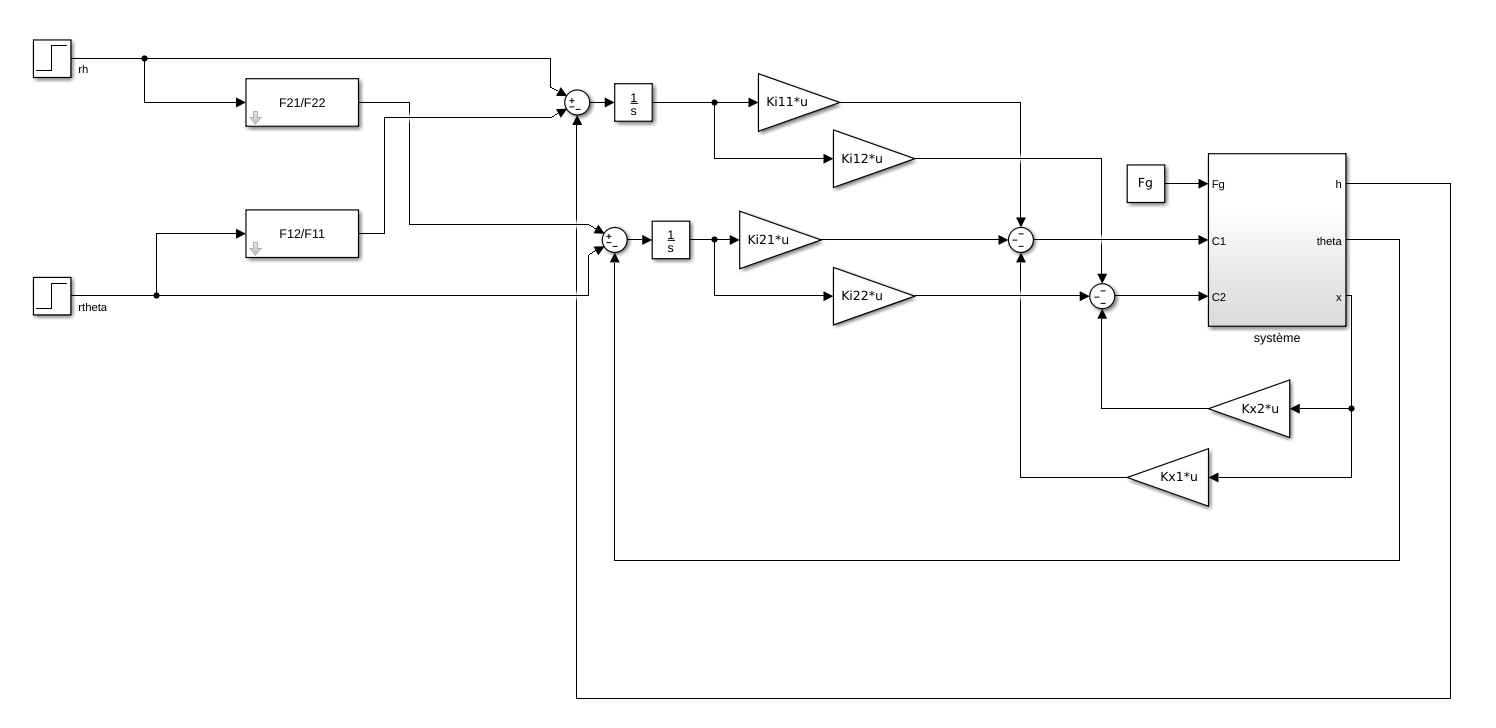

on obtient le tranfert suivant :


$$\left\lbrack \begin{array}{c}
h\left(s\right)\\
\theta \left(s\right)\;
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
F_{r_h \to h}  & F_{r_{\theta \;} \to h} \\
F_{r_h \to \theta \;}  & F_{r_{\theta \;} \to \theta \;} 
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
I & -\frac{F_{r_{\theta \;} \to h} }{F_{r_h \to h} }\\
-\frac{F_{r_{h\;} \to \theta } }{F_{r_{\theta \;} \to \theta } } & I
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
r_h \left(s\right)\\
r_{\theta \;} \left(s\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
F_{r_h \to h} -F_{r_{\theta \;} \to h} \frac{F_{r_{h\;} \to \theta } }{F_{r_{\theta \;} \to \theta } } & 0\\
0 & F_{r_{\theta \;} \to \theta \;} F_{\theta \;} +\ldotp \ldotp \ldotp 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
r_h \left(s\right)\\
r_{\theta \;} \left(s\right)
\end{array}\right\rbrack$$


**ATTENTION,**** cette simplification n'est autorisée que si :**

- la fonction $\frac{F_{r_{\theta \;} \to h} }{F_{r_h \to h} }$ est stable. Autrement le signal de compensation $\frac{F_{r_{\theta \;} \to h} }{F_{r_h \to h} }r_{\theta \;} \left(s\right)$ divergera et mettra les actionneurs en saturation. Si tel est le cas, il n'est pas sûr qu'il existe une solution au problème de découplage. On pourra néanmoins l'attenuer.

- la fonction $\frac{F_{r_{\theta \;} \to h} }{F_{r_h \to h} }$ est propre (d° du numérateur $\le$d° du dénominateur). Si ce n'est pas le cas cela veut dire qu'il faut anticiper les variations du signal ce qui n'est pas causal. Une astuce consite à filtrer les signaux de référence avec des fonctions de transfert $F_h$ et $F_{\theta \;}$  qui possèdent au moins le nombre de pôles manquant et un gain statique unitaire.

Au final on obtient le transfert suivant :


$$\left\lbrack \begin{array}{c}
h\left(s\right)\\
\theta \left(s\right)\;
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
F_{r_h \to h}  & F_{r_{\theta \;} \to h} \\
F_{r_h \to \theta \;}  & F_{r_{\theta \;} \to \theta \;} 
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
I & -\frac{F_{r_{\theta \;} \to h} }{F_{r_h \to h} }\\
-\frac{F_{r_{h\;} \to \theta } }{F_{r_{\theta \;} \to \theta } } & I
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
F_h  & 0\\
0 & F_{\theta \;} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
r_h \left(s\right)\\
r_{\theta \;} \left(s\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
F_{r_h \to h} F_h -F_{r_{\theta \;} \to h} \frac{F_{r_{h\;} \to \theta } }{F_{r_{\theta \;} \to \theta } }F_h  & 0\\
0 & F_{r_{\theta \;} \to \theta \;} F_{\theta \;} +\ldotp \ldotp \ldotp 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
r_h \left(s\right)\\
r_{\theta \;} \left(s\right)
\end{array}\right\rbrack$$


qui correspond à la situation suivante :

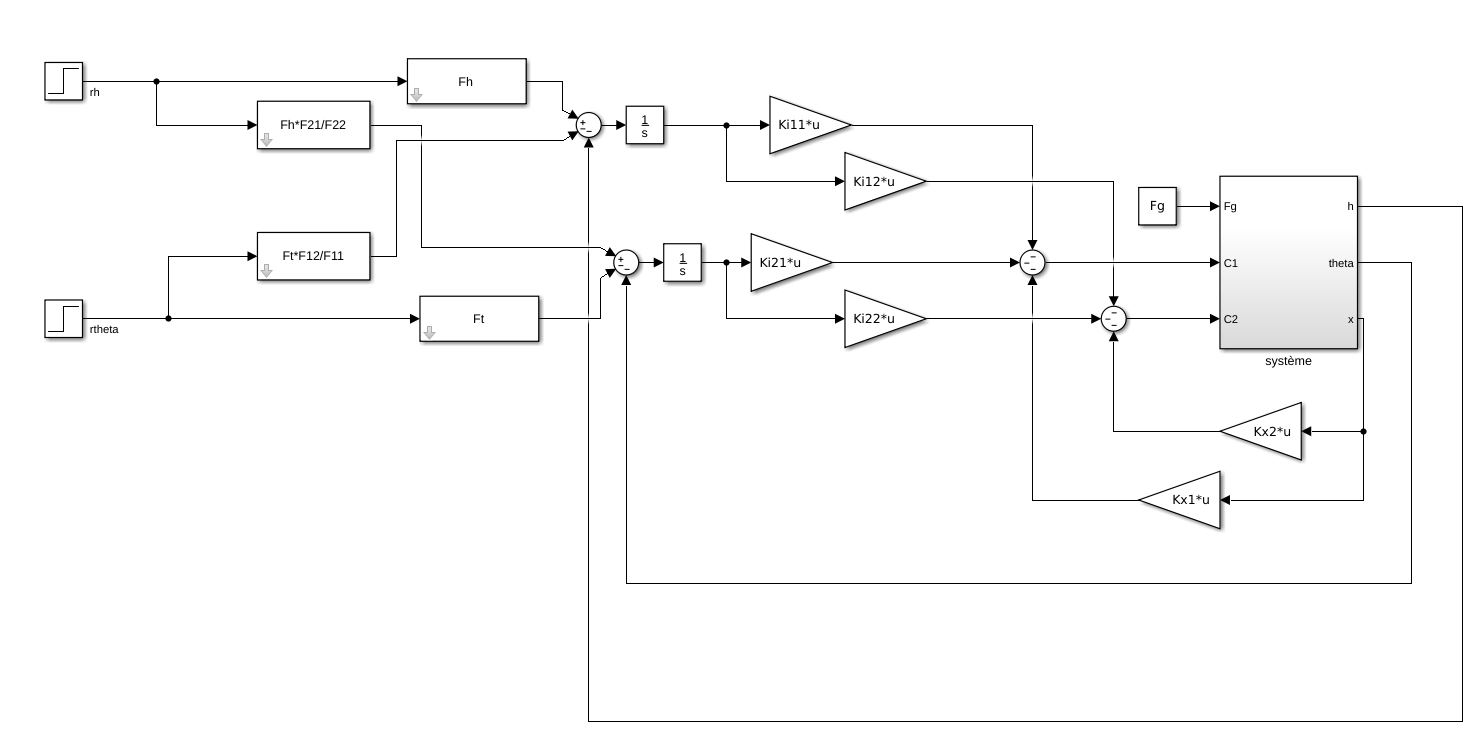

Comme nous avons placé des **intégrateurs** sur les erreurs en $\theta \;$ et $h$, les fonctions de transfert $F_{r_h \to h}$** et **$F_{r_{\theta \;} \to \theta \;}$** ont forcément un gain statique unitaire et les fonctions **$F_{r_{\theta \;} \to h}$** et**$F_{r_h \to \theta \;}$**un gain statique nul**. On peut en déduire que le système de découplage n'influera pas le gain statique final :


$$\left\lbrack \begin{array}{c}
h\left(0\right)\\
\theta \left(0\right)\;
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
F_{r_h \to h} F_h -F_{r_{\theta \;} \to h} \frac{F_{r_{h\;} \to \theta } }{F_{r_{\theta \;} \to \theta } }F_h  & 0\\
0 & F_{r_{\theta \;} \to \theta \;} F_{\theta \;} +\ldotp \ldotp \ldotp 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
r_h \left(0\right)\\
r_{\theta \;} \left(0\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1\times \;1-0\times \;\frac{0}{1}\times 1 & 0\\
0 & \ldotp \ldotp \ldotp 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
r_h \left(0\right)\\
r_{\theta \;} \left(0\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
r_h \left(0\right)\\
r_{\theta \;} \left(0\right)
\end{array}\right\rbrack$$


**Remaque :** Bien que le gain statique final soit bon, le système de découplage change le transfert entre les consignes et les sorties. Ceci change le comportement et peut dont affecter les performances. Il est toujours possible de gommer cet effet en modifiant les fitres $F_h$ et $F_{\theta \;}$(en vérifiant toujours la stabilité et la causalité). 

**Remarque : **on peut également appliqer ce principe sur le système en boucle ouverte sur les transfert ou sur la représentation d'état. Dans ce cas, on obtiendra plusieurs systèmes indépendants à piloter. L'efficacité (temps de conception, robustesse) dépend de la situation. Cette deuxième solution présente l'avantage de ne pas altérer le transfert final (dans le cas nominal).

**Remarque :** les méthodes de découplages et de compensation peuvent être sensible aux erreur paramétriques et aux aux nonlinéarité du modèle. Une analyse à postériori est recommandée. 

**Attention :** si on demande à Matlab de faire le calcul de la matrice de transfert résultante, il ne sera pas capable de détecter que cela fait 0 sur l'anti-diagonale. Pour le constater, if faut tracer le diagramme de Bode et observer le gain très faible.

comph = minreal(W('h','rtheta')/W('h','rh'))


comph =
 
  From input "h" to output "h":
  -0.8558 s^4 - 192.5 s^3 - 207 s^2 - 81.26 s - 4.79e-15
  ------------------------------------------------------
        s^4 + 236.6 s^3 + 3029 s^2 + 4782 s + 2632
 
Continuous-time transfer function.


compt = minreal(W('\theta','rh')/W('\theta','rtheta'))


compt =
 
  From input "\theta" to output "\theta":
  -1.168 s^5 - 134.9 s^4 - 586.8 s^3 - 534.8 s^2 - 189.9 s + 3.784e-15
  --------------------------------------------------------------------
   s^5 + 508.6 s^4 + 2.837e04 s^3 + 3.563e04 s^2 + 2.182e04 s + 6152
 
Continuous-time transfer function.



C=[1 -comph;
    -compt 1];

C.InputName = {'h','theta'};
C.OutputName = {'rh','rtheta'}


C =
 
  From input "h" to output...
   rh:  1
 
            1.168 s^5 + 134.9 s^4 + 586.8 s^3 + 534.8 s^2 + 189.9 s - 3.784e-15
   rtheta:  -------------------------------------------------------------------
             s^5 + 508.6 s^4 + 2.837e04 s^3 + 3.563e04 s^2 + 2.182e04 s + 6152
 
  From input "theta" to output...
        0.8558 s^4 + 192.5 s^3 + 207 s^2 + 81.26 s + 4.79e-15
   rh:  -----------------------------------------------------
             s^4 + 236.6 s^3 + 3029 s^2 + 4782 s + 2632
 
   rtheta:  1
 
Continuous-time transfer function.


%
sys_bf_decouple = sys_bf({'h','\theta'},{'rh','rtheta'})*C;

% le terme anti-diagonal est proche de 0 (à cause des erreur de calcul numériques)
Wcouplage = tf(sys_bf_decouple({'h'},'theta'))


Wcouplage =
 
  From input "theta" to output "h":
                         1.417e-12 s^8 - 2.088e-09 s^7 - 1.568e-06 s^6 - 0.0002447 s^5 - 0.003246 s^4 - 0.007336 s^3 - 0.005596 s^2 - 0.001703 s - 2.66e-08
  --------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^12 + 545.4 s^11 + 9.622e04 s^10 + 5.942e06 s^9 + 1.195e08 s^8 + 9.665e08 s^7 + 3.247e09 s^6 + 6.046e09 s^5 + 6.99e09 s^4 + 5.252e09 s^3 + 2.557e09 s^2 + 7.561e08 s + 1.053e08
 
Continuous-time transfer function.


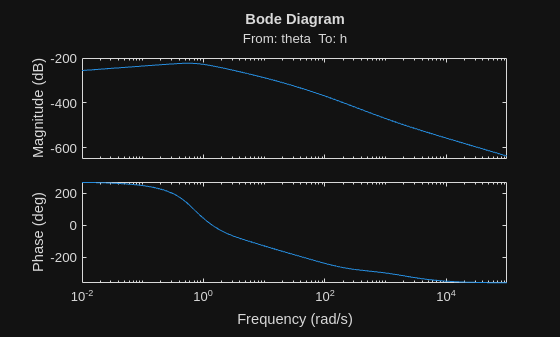

bode(Wcouplage)

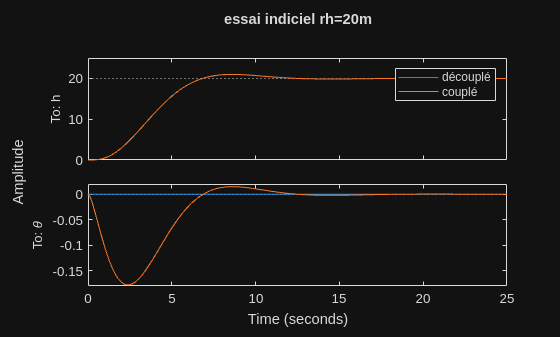


% comparaison avec et sans le découplage :
step(sys_bf_decouple({'h','\theta'},'h')*20,sys_bf({'h','\theta'},'rh')*20);
legend('découplé','couplé');
title('essai indiciel rh=20m')

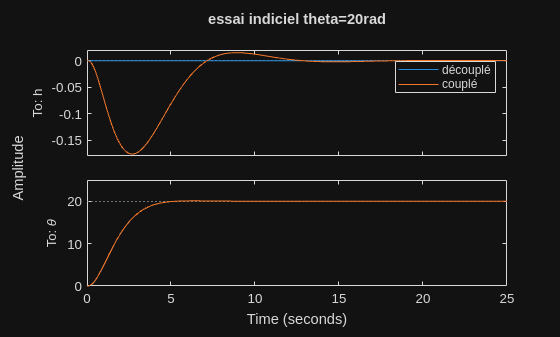

% comparaison avec et sans le découplage :
step(sys_bf_decouple({'h','\theta'},'theta')*20,sys_bf({'h','\theta'},'rtheta')*20);
legend('découplé','couplé');
title('essai indiciel theta=20rad')

**N'hésitez pas à 'jouer' avec les valeurs ou regarder ce quil se passe si on fait plutôt un placement de pôles, ...**